% SCENARIO 1: DEAD STATE ANALYSIS

clear; clc; close all;

% 1. Lorenz Parameter (The "Cold" System)
sigma = 10; 
rho = 0.5;   
beta = 8/3;  

% 2. ODE45 
t_raw = linspace(0, 10, 1000); 
lorenz_odes = @(t, s) [sigma*(s(2)-s(1)); s(1)*(rho-s(3))-s(2); s(1)*s(2)-beta*s(3)];
[t_solve, states] = ode45(lorenz_odes, t_raw, [1; 1; 1]);

% 3. Interpolate 
t_1000 = linspace(0, 10, 1000);
x = interp1(t_solve, states(:,1), t_1000)';
y = interp1(t_solve, states(:,2), t_1000)';
z = interp1(t_solve, states(:,3), t_1000)';

% 4. Statistical Data


disp('   SCENARIO 1: DEAD STATE (\rho = 0.5)  ');

   SCENARIO 1: DEAD STATE (\rho = 0.5)  


fprintf('X -> Mean: %7.4f | Std: %7.4f | Min: %7.4f | Max: %7.4f\n', mean(x), std(x), min(x), max(x));

X -> Mean:  0.1425 | Std:  0.2035 | Min:  0.0049 | Max:  1.0000


fprintf('Y -> Mean: %7.4f | Std: %7.4f | Min: %7.4f | Max: %7.4f\n', mean(y), std(y), min(y), max(y));

Y -> Mean:  0.1326 | Std:  0.1861 | Min:  0.0047 | Max:  1.0000


fprintf('Z -> Mean: %7.4f | Std: %7.4f | Min: %7.4f | Max: %7.4f\n', mean(z), std(z), min(z), max(z));

Z -> Mean:  0.0590 | Std:  0.1602 | Min:  0.0000 | Max:  1.0000


---------------------------------------


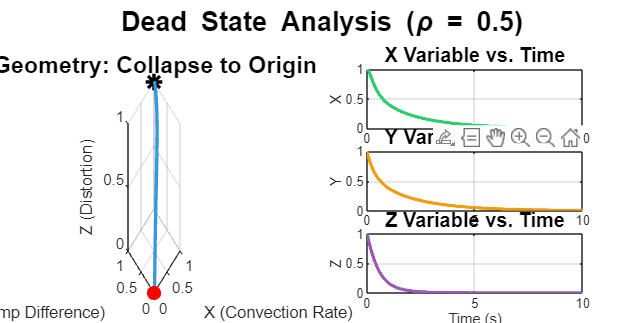



figure('Name', 'Dead State Analysis', 'Color', 'w', 'Position', [100, 200, 1200, 600]);

% Left Panel: The 3D Phase Space
subplot(1, 2, 1);
plot3(x, y, z, 'Color', [0.20, 0.60, 0.86], 'LineWidth', 2); % Soft Blue
hold on; 
plot3(1, 1, 1, 'k*', 'MarkerSize', 10, 'LineWidth', 2); % Start point
plot3(0, 0, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % End point (The Origin)
grid on; axis tight;
xlabel('X (Convection Rate)'); 
ylabel('Y (Temp Difference)'); 
zlabel('Z (Distortion)');
title('Geometry: Collapse to Origin', 'FontSize', 14);
view(-45, 25);

% Right Panel: The Time-Series
subplot(3, 2, 2);
plot(t_1000, x, 'Color', [0.18, 0.80, 0.44], 'LineWidth', 2);
title('X Variable vs. Time', 'FontSize', 12);
ylabel('X'); grid on; xlim([0 10]);

subplot(3, 2, 4);
plot(t_1000, y, 'Color', [0.95, 0.61, 0.07], 'LineWidth', 2); 
title('Y Variable vs. Time', 'FontSize', 12);
ylabel('Y'); grid on; xlim([0 10]);

subplot(3, 2, 6);
plot(t_1000, z, 'Color', [0.61, 0.35, 0.71], 'LineWidth', 2); 
title('Z Variable vs. Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Z'); grid on; xlim([0 10]);

sgtitle('Dead State Analysis (\rho = 0.5)', 'FontSize', 16, 'FontWeight', 'bold');


drawnow; shg;

% 6. Feature Expansion (Uplifting the Data)
xy = x .* y;
yz = y .* z;
xz = x .* z; 
x_sq = x.^2;
y_sq = y.^2;
z_sq = z.^2;

% Combine into a Feature Matrix (1000 rows x 9 columns)
% Columns: [t, x, y, z, xy, yz, xz, x^2, y^2, z^2]
feature_matrix = [t_1000', x, y, z, xy, yz, xz, x_sq, y_sq, z_sq];

% The first few rows of the "Uplifted" data
disp('Uplifted Data Table (First 5 samples):');

Uplifted Data Table (First 5 samples):


T = table(t_1000(1:5)', x(1:5), y(1:5), z(1:5), xy(1:5), x_sq(1:5), ...
    'VariableNames', {'Time', 'X', 'Y', 'Z', 'XY', 'X_sq'});
disp(T);

     Time         X          Y          Z         XY        X_sq  
    _______    _______    _______    _______    _______    _______

          0          1          1          1          1          1
    0.01001    0.99928    0.98514    0.98346    0.98443    0.99856
    0.02002    0.99723    0.97061     0.9672    0.96791    0.99446
    0.03003      0.994    0.95638     0.9512    0.95065    0.98804
    0.04004    0.98974    0.94248    0.93545    0.93281    0.97959



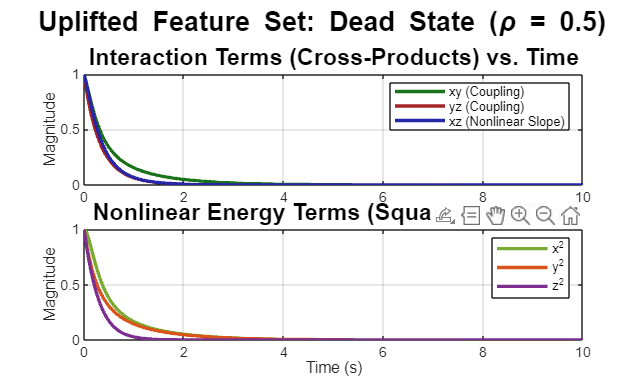


% 7. VISUALIZING THE UPLIFTED FEATURES

figure('Name', 'Uplifted Feature Analysis', 'Color', 'w', 'Position', [150, 150, 1200, 700]);

% Subplot A: Cross-Product Terms (Interactions)
subplot(2, 1, 1);
plot(t_1000, xy, 'LineWidth', 2, 'Color', [0.10, 0.45, 0.10]); hold on;
plot(t_1000, yz, 'LineWidth', 2, 'Color', [0.65, 0.15, 0.15]);
plot(t_1000, xz, 'LineWidth', 2, 'Color', [0.15, 0.15, 0.65]);
grid on;
title('Interaction Terms (Cross-Products) vs. Time', 'FontSize', 14);
ylabel('Magnitude');
legend('xy (Coupling)', 'yz (Coupling)', 'xz (Nonlinear Slope)', 'Location', 'northeast');

% Subplot B: Squared Terms
subplot(2, 1, 2);
plot(t_1000, x_sq, 'LineWidth', 2, 'Color', [0.47, 0.67, 0.19]); hold on;
plot(t_1000, y_sq, 'LineWidth', 2, 'Color', [0.85, 0.33, 0.10]);
plot(t_1000, z_sq, 'LineWidth', 2, 'Color', [0.49, 0.18, 0.56]);
grid on;
title('Nonlinear Energy Terms (Squared) vs. Time', 'FontSize', 14);
xlabel('Time (s)');
ylabel('Magnitude');
legend('x^2', 'y^2', 'z^2', 'Location', 'northeast');


sgtitle(['Uplifted Feature Set: Dead State (\rho = ', num2str(rho), ')'], ...
    'FontSize', 16, 'FontWeight', 'bold');


% Statistical Analysis for the Uplifted Terms
disp(' ');

disp('   STATISTICS: UPLIFTED FEATURES       ');

   STATISTICS: UPLIFTED FEATURES       


fprintf('XY -> Mean: %7.4f | Max: %7.4f\n', mean(xy), max(xy));

XY -> Mean:  0.0567 | Max:  1.0000


fprintf('YZ -> Mean: %7.4f | Max: %7.4f\n', mean(yz), max(yz));

YZ -> Mean:  0.0356 | Max:  1.0000


fprintf('XZ -> Mean: %7.4f | Max: %7.4f\n', mean(xz), max(xz));

XZ -> Mean:  0.0389 | Max:  1.0000


fprintf('X2 -> Mean: %7.4f | Max: %7.4f\n', mean(x_sq), max(x_sq));

X2 -> Mean:  0.0617 | Max:  1.0000


fprintf('Y2 -> Mean: %7.4f | Max: %7.4f\n', mean(y_sq), max(y_sq));

Y2 -> Mean:  0.0522 | Max:  1.0000


fprintf('Z2 -> Mean: %7.4f | Max: %7.4f\n', mean(z_sq), max(z_sq));

Z2 -> Mean:  0.0291 | Max:  1.0000


---------------------------------------



% SCENARIO 1: HANKEL-DMD FORECASTING (DEAD STATE)


% Normalize for numerical stability in DMD
mu_x = mean(x); std_x = std(x); norm_x = (x - mu_x)/std_x;
mu_y = mean(y); std_y = std(y); norm_y = (y - mu_y)/std_y;
mu_z = mean(z); std_z = std(z); norm_z = (z - mu_z)/std_z;

% 2. KOOPMAN LIFTING & HANKELIZATION

Lifted = [norm_x'; norm_y'; norm_z';             % 1-3: Linear
          norm_x'.*norm_y'; norm_x'.*norm_z';     % 4-5: Cross-Terms
          norm_x'.^2; norm_y'.^2; norm_z'.^2];   % 6-8: Nonlinear Squares
          
L = 25;               % Delay embedding depth (Stacking 25 time steps)
num_vars = 8;         % Number of lifted variables
N = length(norm_x);   % 1000 points
K = N - L + 1;        % Total available columns in Hankel matrix

H = zeros(num_vars * L, K);
for k = 1:K
    window = Lifted(:, k:k+L-1); 
    H(:, k) = window(:); 
end

% 3. SPLIT, SVD & DMD
train_cols = floor(K * 0.3); 
H_train = H(:, 1:train_cols);
H_test = H(:, train_cols+1:end);

X = H_train(:, 1:end-1); 
X_prime = H_train(:, 2:end);

% SVD for Dimensionality Reduction
[U, S, V] = svd(X, 'econ');
r = 60; % Rank truncation
Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

% Compute DMD Operator
A_tilde = (Ur') * X_prime * Vr / Sr;
[W, D] = eig(A_tilde); 
lambdas = diag(D);
Phi = X_prime * Vr / Sr * W; % DMD Modes
b = Phi \ X(:, 1);           % Initial amplitudes

% 4. FORECASTING
total_snapshots = K; 
time_dynamics = zeros(r, total_snapshots);
for step = 0:total_snapshots-1
    time_dynamics(:, step+1) = (b .* (lambdas .^ step)); 
end
signal_forecast_norm = real(Phi * time_dynamics);

% 5. UN-NORMALIZE & METRICS

pred_x = (signal_forecast_norm(1,:) .* std_x) + mu_x;
truth_x = (H(1,:) .* std_x) + mu_x;

actual = truth_x(train_cols+1:end); 
predicted = pred_x(train_cols+1:end);
err_vec = abs(actual - predicted);
rmse = sqrt(mean(err_vec.^2));
mae = mean(err_vec);

% 6. DISPLAY STATISTICS
num_forecasted = length(actual);
[rows_H, cols_H] = size(H);



disp('   HANKEL-DMD ANALYSIS: DEAD STATE (\rho=0.5)  ');

   HANKEL-DMD ANALYSIS: DEAD STATE (\rho=0.5)  


fprintf('Matrix Rows (num_vars * L): %d\n', rows_H);

Matrix Rows (num_vars * L): 200


fprintf('Matrix Columns (K):         %d\n', cols_H);

Matrix Columns (K):         976


fprintf('Truncation Rank (r):        %d\n', r);

Truncation Rank (r):        60


fprintf('Training Data Points:       %d\n', train_cols);

Training Data Points:       292


fprintf('Forecasted Data Points:     %d\n', num_forecasted);

Forecasted Data Points:     684


-----------------------------------------------


fprintf('RMSE: %.6f | MAE: %.6f\n', rmse, mae);

RMSE: 0.000513 | MAE: 0.000382


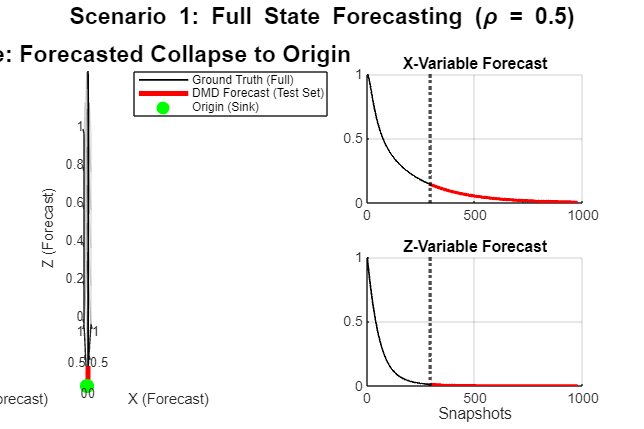




figure('Name', 'Hankel-DMD 3D Phase Forecast', 'Color', 'w', 'Position', [100, 100, 1200, 800]);

% A. UN-NORMALIZE ALL 3 VARIABLES
% Rows 1, 2, and 3 of signal_forecast_norm are x, y, and z
pred_all_norm = signal_forecast_norm(1:3, :);
pred_x_full = (pred_all_norm(1,:) .* std_x) + mu_x;
pred_y_full = (pred_all_norm(2,:) .* std_y) + mu_y;
pred_z_full = (pred_all_norm(3,:) .* std_z) + mu_z;


truth_x_full = (H(1,:) .* std_x) + mu_x;
truth_y_full = (H(2,:) .* std_y) + mu_y;
truth_z_full = (H(3,:) .* std_z) + mu_z;

%  B. 3D PHASE ATTRACTOR RECONSTRUCTION 
subplot(2, 2, [1, 3]); 
plot3(truth_x_full, truth_y_full, truth_z_full, 'k-', 'LineWidth', 1); hold on;

plot3(pred_x_full(train_cols+1:end), pred_y_full(train_cols+1:end), ...
      pred_z_full(train_cols+1:end), 'r-', 'LineWidth', 3);
plot3(0,0,0, 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8);
grid on; view(-45, 25);
xlabel('X (Forecast)'); ylabel('Y (Forecast)'); zlabel('Z (Forecast)');
title('3D Phase Space: Forecasted Collapse to Origin', 'FontSize', 14);
legend('Ground Truth (Full)', 'DMD Forecast (Test Set)', 'Origin (Sink)');

% C. X-VARIABLE TIME SERIES
subplot(2, 2, 2); hold on;
plot(1:K, truth_x_full, 'k', 'LineWidth', 1);
plot(train_cols+1:K, pred_x_full(train_cols+1:end), 'r-', 'LineWidth', 2);
xline(train_cols, 'k:', 'LineWidth', 2);
title('X-Variable Forecast'); grid on;

%  D. Z-VARIABLE TIME SERIES
subplot(2, 2, 4); hold on;
plot(1:K, truth_z_full, 'k', 'LineWidth', 1);
plot(train_cols+1:K, pred_z_full(train_cols+1:end), 'r-', 'LineWidth', 2);
xline(train_cols, 'k:', 'LineWidth', 2);
title('Z-Variable Forecast'); grid on;
xlabel('Snapshots');

sgtitle(['Scenario 1: Full State Forecasting (\rho = ', num2str(rho), ')'], 'FontWeight', 'bold');

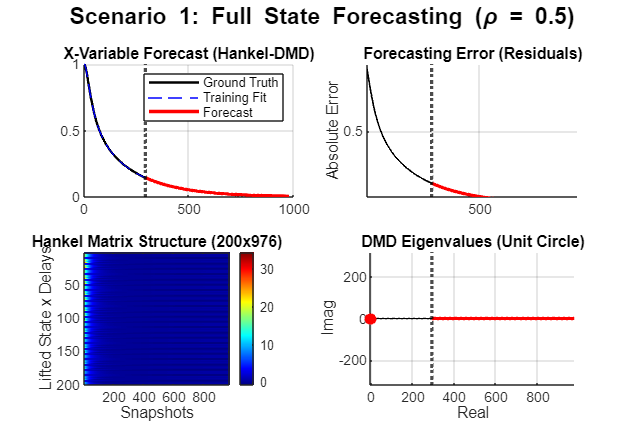


% Forecast Plot
subplot(2,2,1); hold on;
plot(1:K, truth_x, 'k', 'LineWidth', 1.5, 'DisplayName', 'Ground Truth'); 
plot(1:train_cols, pred_x(1:train_cols), 'b--', 'DisplayName', 'Training Fit');
plot(train_cols+1:K, predicted, 'r-', 'LineWidth', 2, 'DisplayName', 'Forecast');
xline(train_cols, 'k:', 'LineWidth', 2, 'HandleVisibility', 'off');
title('X-Variable Forecast (Hankel-DMD)'); grid on; legend;

% Error Plot
subplot(2,2,2); 
area(train_cols+1:K, err_vec, 'FaceColor', [1 0.4 0.4], 'EdgeColor', 'r');
title('Forecasting Error (Residuals)'); grid on; ylabel('Absolute Error');

% Hankel Matrix Structure
subplot(2,2,3);
imagesc(H); colormap(jet); colorbar;
title(['Hankel Matrix Structure (', num2str(rows_H), 'x', num2str(cols_H), ')']);
xlabel('Snapshots'); ylabel('Lifted State x Delays');

% Eigenvalues 
subplot(2,2,4); hold on;
th = linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerFaceColor', 'r');
title('DMD Eigenvalues (Unit Circle)'); grid on; axis equal;
xlabel('Real'); ylabel('Imag');

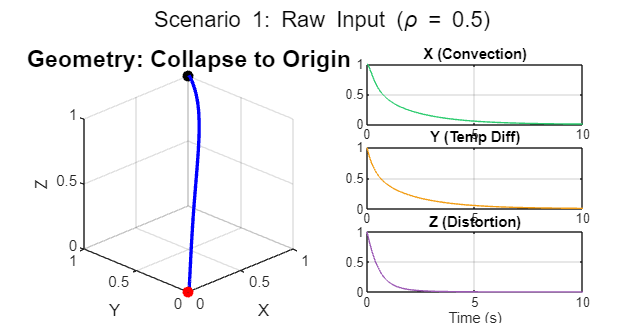


% SCENARIO 1: DEAD STATE ANALYSIS (1000 PTS | 15 TERMS)

clear; clc; close all;

% 1. DATA GENERATION & INTERPOLATION
sigma = 10; rho = 0.5; beta = 8/3;
t_max = 10; num_points = 1000; 
t_raw = linspace(0, t_max, num_points); 

lorenz_odes = @(t, s) [sigma*(s(2)-s(1)); s(1)*(rho-s(3))-s(2); s(1)*s(2)-beta*s(3)];
[t_solve, states] = ode45(lorenz_odes, t_raw, [1; 1; 1]);

t_1000 = linspace(0, t_max, num_points);
x = interp1(t_solve, states(:,1), t_1000)';
y = interp1(t_solve, states(:,2), t_1000)';
z = interp1(t_solve, states(:,3), t_1000)';

% 1B. INITIAL RAW DATA PLOTS 
figure('Name', 'Scenario 1: Raw Dead State Data', 'Color', 'w', 'Position', [50, 50, 1200, 600]);
subplot(1, 2, 1);
plot3(x, y, z, 'b', 'LineWidth', 2); hold on;
plot3(x(1), y(1), z(1), 'ko', 'MarkerFaceColor', 'k'); 
plot3(0,0,0, 'ro', 'MarkerFaceColor', 'r'); 
grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
title('Geometry: Collapse to Origin', 'FontSize', 14); view(-45, 25);

subplot(3, 2, 2); plot(t_1000, x, 'Color', [0.18, 0.80, 0.44]); title('X (Convection)'); grid on;
subplot(3, 2, 4); plot(t_1000, y, 'Color', [0.95, 0.61, 0.07]); title('Y (Temp Diff)'); grid on;
subplot(3, 2, 6); plot(t_1000, z, 'Color', [0.61, 0.35, 0.71]); title('Z (Distortion)'); grid on;
xlabel('Time (s)'); sgtitle('Scenario 1: Raw Input (\rho = 0.5)');


% 2. KOOPMAN LIFTING: 15-VARIABLE DICTIONARY
mu_x = mean(x); std_x = std(x); nx = (x - mu_x)/std_x;
mu_y = mean(y); std_y = std(y); ny = (y - mu_y)/std_y;
mu_z = mean(z); std_z = std(z); nz = (z - mu_z)/std_z;

Lifted = [nx'; ny'; nz'; ...                 
          nx'.^2; ny'.^2; nz'.^2; ...         
          nx'.*ny'; nx'.*nz'; ny'.*nz'; ...   
          nx'.^3; ny'.^3; nz'.^3; ...         
          (nx'.^2).*ny'; (nx'.^2).*nz'; (ny'.^2).*nz']; 

% 3. HANKELIZATION
L = 40; num_vars = size(Lifted, 1); 
N = length(nx); K = N - L + 1;
H = zeros(num_vars * L, K);
for k = 1:K, window = Lifted(:, k:k+L-1); H(:, k) = window(:); end

% 4. DMD & FORECAST 
train_cols = floor(K * 0.4); 
X = H(:, 1:train_cols-1); X_prime = H(:, 2:train_cols);

[U, S, V] = svd(X, 'econ');
r = 60; Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

A_tilde = (Ur') * X_prime * Vr / Sr;
[W, D] = eig(A_tilde); lambdas = diag(D);
Phi = X_prime * Vr / Sr * W; 
b = Phi \ X(:, 1);           

time_dynamics = zeros(r, K);
for step = 0:K-1, time_dynamics(:, step+1) = (b .* (lambdas .^ step)); end
signal_forecast_norm = real(Phi * time_dynamics);

% 5. UN-NORMALIZE
pred_x = (signal_forecast_norm(1,:) .* std_x) + mu_x;
pred_y = (signal_forecast_norm(2,:) .* std_y) + mu_y;
pred_z = (signal_forecast_norm(3,:) .* std_z) + mu_z;
truth_x = (H(1,:) .* std_x) + mu_x;
rmse_val = sqrt(mean((truth_x(train_cols+1:end) - pred_x(train_cols+1:end)).^2));



disp('   SCENARIO 1: DEAD STATE DMD ANALYSIS         ');

   SCENARIO 1: DEAD STATE DMD ANALYSIS         


fprintf('Matrix Rows: %d | K: %d\n', size(H,1), K);

Matrix Rows: 600 | K: 961


fprintf('Training Points: %d | Forecast Points: %d\n', train_cols, K - train_cols);

Training Points: 384 | Forecast Points: 577


fprintf('RMSE: %.8f\n', rmse_val);

RMSE: 0.00186912


% 7. DASHBOARD VISUALIZATION
figure('Name', 'Dead State DMD Forecast', 'Color', 'w', 'Position', [100, 100, 1200, 800]);

% 3D Phase Forecast
subplot(2, 2, [1, 3]);
plot3(x, y, z, 'Color', [0.8 0.8 0.8], 'LineWidth', 0.5); hold on;
plot3(pred_x(1:train_cols), pred_y(1:train_cols), pred_z(1:train_cols), 'b-', 'LineWidth', 1);
plot3(pred_x(train_cols+1:end), pred_y(train_cols+1:end), pred_z(train_cols+1:end), 'r-', 'LineWidth', 2);
grid on; view(-45, 25); xlabel('X'); ylabel('Y'); zlabel('Z');
title(['3D Forecast: 15-Term Koopman (\rho = 0.5)']);
legend('Full Truth', 'Training Fit', 'DMD Forecast');

% X-Variable Time Series
subplot(2, 2, 2); hold on;
plot(1:K, truth_x, 'k', 'LineWidth', 1);
plot(train_cols+1:K, pred_x(train_cols+1:end), 'r', 'LineWidth', 1.5);
xline(train_cols, 'k:'); title('X Forecast (Decay)'); grid on;

% Eigenvalues
subplot(2, 2, 4); hold on;
th = linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r');
title('DMD Eigenvalues: Strong Dissipation'); 
grid on; axis equal; xlabel('Real'); ylabel('Imag');

sgtitle(['Scenario 1: Dead State (\rho = 0.5) | RMSE: ', num2str(rmse_val, '%.8f')], 'FontWeight', 'bold');